%% =========================================================
%  DISTANCE + SPATIAL DISPERSION
%  GROUP SCOUT vs LESION SCOUT
%
%  Case adapted to your workflow:
%   - cortex exported from Brainstorm
%   - lesion scout exported separately  -> scout_lesion_mask.mat
%   - group scout exported separately   -> scout_lesion_spike.mat
%
%  OUTPUT:
%   - Minimum distance to lesion
%   - Spatial dispersion (RMS, no intensities)
%   - Summary plots
%% =========================================================

clear; clc; close all;

%% =========================
% 1) FILES: EDIT THESE PATHS
%% =========================

cortex_file = 'C:\Users\prego\Documents\brainstorm_db\ESI_10-10_12-03-2026_AA\anat\AA\tess_cortex_pial_low.mat';
mask_file   = 'C:\Users\prego\Documents\scout_lesion_mask.mat';   % lesión
group_file  = 'C:\Users\prego\Documents\scout_lesion_spike.mat';  % spike

group_name = 'Spike';

% Brainstorm usually stores cortex coordinates in meters.
% Multiply by 1000 to display results in mm.
unit_scale = 1;


%% =========================
% 2) LOAD DATA
%% =========================

sCortex = load(cortex_file);
mask    = load(mask_file);
spike   = load(group_file);

% --- Cortex vertices ---
if isfield(sCortex, 'Vertices')
    Vertices = sCortex.Vertices;
elseif isfield(sCortex, 'sSurf') && isfield(sCortex.sSurf, 'Vertices')
    Vertices = sCortex.sSurf.Vertices;
else
    error('No se ha encontrado el campo Vertices en el archivo del cortex.');
end

% --- Cortex faces (optional, only for visualization) ---
Faces = [];
if isfield(sCortex, 'Faces')
    Faces = sCortex.Faces;
elseif isfield(sCortex, 'sSurf') && isfield(sCortex.sSurf, 'Faces')
    Faces = sCortex.sSurf.Faces;
end


%% =========================
% 3) GET LESION SCOUT VERTICES
%% =========================

if ~isfield(mask, 'Scouts') || isempty(mask.Scouts)
    error('El archivo de lesión no contiene el campo Scouts o está vacío.');
end

if length(mask.Scouts) > 1
    warning('El archivo de lesión contiene más de un scout. Se usará el primero.');
end

lesion_vertices = mask.Scouts(1).Vertices;

if isempty(lesion_vertices)
    error('El scout de lesión no contiene vértices.');
end

lesion_coords = Vertices(lesion_vertices, :) * unit_scale;


%% =========================
% 4) GET GROUP SCOUT VERTICES
%% =========================

if ~isfield(spike, 'Scouts') || isempty(spike.Scouts)
    error('El archivo del grupo no contiene el campo Scouts o está vacío.');
end

if length(spike.Scouts) > 1
    warning('El archivo del grupo contiene más de un scout. Se usará el primero.');
end

group_vertices = spike.Scouts(1).Vertices;

if isempty(group_vertices)
    error('El scout del grupo no contiene vértices.');
end

group_coords = Vertices(group_vertices, :) * unit_scale;


%% =========================
% 5) DISTANCE CALCULATION
%% =========================

% Distancia entre cada vértice del grupo y cada vértice de la lesión
D = pdist2(group_coords, lesion_coords);

% Para cada vértice del grupo, distancia mínima a la lesión
d_vertex_to_lesion = min(D, [], 2);

% Métricas principales
min_distance_mm = min(d_vertex_to_lesion);
mean_distance_mm = mean(d_vertex_to_lesion);
median_distance_mm = median(d_vertex_to_lesion);

% Dispersión espacial (RMS no ponderada)
spatial_dispersion_mm = sqrt(mean(d_vertex_to_lesion.^2));

% Desviación estándar clásica de las distancias por vértice
std_distance_mm = std(d_vertex_to_lesion);


%% =========================
% 6) PRINT RESULTS
%% =========================

fprintf('\n========================================\n');

fprintf('GROUP: %s\n', group_name);

GROUP: Spike


fprintf('========================================\n');

fprintf('Vertices in lesion scout: %d\n', length(lesion_vertices));

Vertices in lesion scout: 110


fprintf('Vertices in group scout:  %d\n', length(group_vertices));

Vertices in group scout:  145


fprintf('Minimum distance to lesion: %.4f mm\n', min_distance_mm);

Minimum distance to lesion: 0.0437 mm


fprintf('Mean distance to lesion:    %.4f mm\n', mean_distance_mm);

Mean distance to lesion:    0.0739 mm


fprintf('Median distance to lesion:  %.4f mm\n', median_distance_mm);

Median distance to lesion:  0.0732 mm


fprintf('Spatial dispersion (RMS):   %.4f mm\n', spatial_dispersion_mm);

Spatial dispersion (RMS):   0.0750 mm


fprintf('Std of distances:           %.4f mm\n', std_distance_mm);

Std of distances:           0.0130 mm



ResultsTable = table({group_name}, min_distance_mm, mean_distance_mm, ...
    median_distance_mm, spatial_dispersion_mm, std_distance_mm, ...
    'VariableNames', {'Group','MinDistance_mm','MeanDistance_mm', ...
    'MedianDistance_mm','SpatialDispersion_RMS_mm','StdDistance_mm'});

disp(ResultsTable);

      Group      MinDistance_mm    MeanDistance_mm    MedianDistance_mm    SpatialDispersion_RMS_mm    StdDistance_mm
    _________    ______________    _______________    _________________    ________________________    ______________

    {'Spike'}       0.043714           0.07387            0.073187                 0.075006               0.013049   



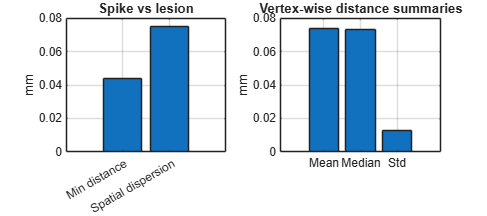



%% =========================
% 7) SUMMARY BAR PLOT
%% =========================

figure('Color','w','Position',[100 100 900 400]);

subplot(1,2,1);
bar([min_distance_mm, spatial_dispersion_mm]);
set(gca, 'XTick', [1 2], ...
         'XTickLabel', {'Min distance', 'Spatial dispersion'});
ylabel('mm');
title([group_name ' vs lesion']);
grid on;

subplot(1,2,2);
bar([mean_distance_mm, median_distance_mm, std_distance_mm]);
set(gca, 'XTick', [1 2 3], ...
         'XTickLabel', {'Mean', 'Median', 'Std'});
ylabel('mm');
title('Vertex-wise distance summaries');
grid on;

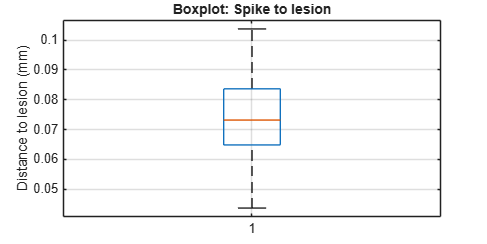



%% =========================
% 8) BOXPLOT / RAINCLOUD STYLE
%% =========================

figure('Color','w','Position',[150 150 800 400]);

if exist('raincloud_plot','file') == 2
    cb = [0.8 0.5 0.4];
    raincloud_plot(d_vertex_to_lesion(:), ...
        'box_on', 1, ...
        'color', cb, ...
        'bandwidth', .2, ...
        'density_type', 'ks');
    title(['Raincloud Plot: ' group_name ' to lesion']);
    xlabel('Distance to lesion (mm)');
    box off;
else
    boxplot(d_vertex_to_lesion(:));
    ylabel('Distance to lesion (mm)');
    title(['Boxplot: ' group_name ' to lesion']);
    grid on;
end

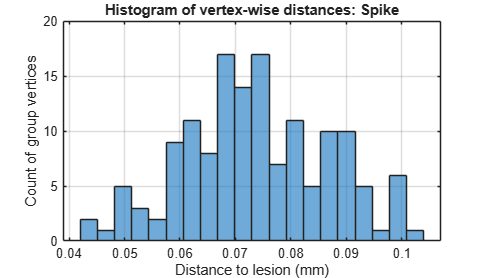



%% =========================
% 9) HISTOGRAM
%% =========================

figure('Color','w','Position',[200 200 700 400]);
histogram(d_vertex_to_lesion, 20);
xlabel('Distance to lesion (mm)');
ylabel('Count of group vertices');
title(['Histogram of vertex-wise distances: ' group_name]);
grid on;

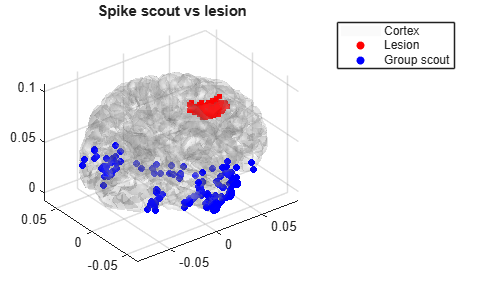



%% =========================
% 10) 3D VISUALIZATION
%% =========================

figure('Color','w');

if ~isempty(Faces)
    trisurf(Faces, ...
        Vertices(:,1)*unit_scale, ...
        Vertices(:,2)*unit_scale, ...
        Vertices(:,3)*unit_scale, ...
        'FaceColor', [0.85 0.85 0.85], ...
        'EdgeColor', 'none', ...
        'FaceAlpha', 0.12);
    axis equal; hold on;
    lighting gouraud; camlight;
else
    scatter3(Vertices(:,1)*unit_scale, ...
             Vertices(:,2)*unit_scale, ...
             Vertices(:,3)*unit_scale, ...
             1, [0.8 0.8 0.8], 'filled');
    axis equal; hold on;
end

scatter3(lesion_coords(:,1), lesion_coords(:,2), lesion_coords(:,3), ...
    20, 'r', 'filled');

scatter3(group_coords(:,1), group_coords(:,2), group_coords(:,3), ...
    25, 'b', 'filled');

legend({'Cortex','Lesion','Group scout'}, 'Location', 'bestoutside');
title([group_name ' scout vs lesion']);
view(3);
rotate3d on;